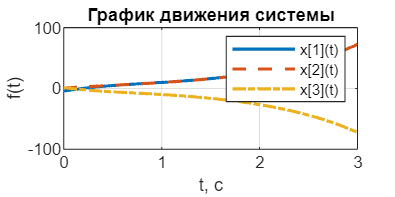

open_system('Lab7_4');
set_param('Lab7_4/y1', 'VariableName', 'y1')
set_param('Lab7_4/y2', 'VariableName', 'y2')
set_param('Lab7_4/y3', 'VariableName', 'y3')
set_param('Lab7_4/u', 'VariableName', 'u')
set_param('Lab7_4/fun', 'VariableName', 'fun')

out = sim('Lab7_4');

t=0.01:0.01:3;
y= -3*exp(-3*t).*cos(2*t) - 2*exp(-3*t).*sin(2*t);

figure('Position', [100 100 800 400])
plot(out.y1,'-', 'LineWidth',1.5)
hold on
plot(out.y2,'--', 'LineWidth',1.5)
plot(out.y3,'-.', 'LineWidth',1.5)

grid()
%pbaspect([2 1 1]);
%ylim([-8.5 5.5])
%ti = [-8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5]
%yticks(floor(min(ti)):ceil(max(ti)));
title('График движения системы')
legend('x[1](t)', 'x[2](t)', 'x[3](t)')
ylabel('f(t)')
xlabel('t, с')
hold off

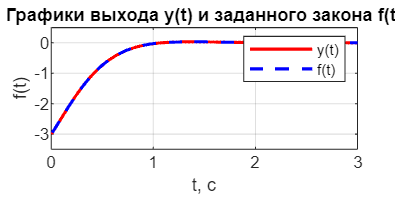


plot(out.u,'r', 'LineWidth', 1.5)
hold on
plot(t, y,'b--', 'LineWidth', 1.5)

grid("on")
title('Графики выхода y(t) и заданного закона f(t)')
legend('y(t)', 'f(t)')
ylabel('f(t)')
xlabel('t, с')
ylim([-3.5 0.5])
hold off

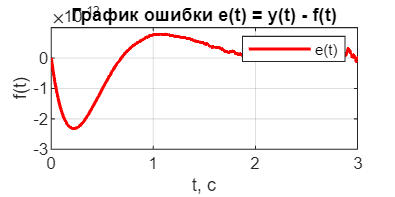


plot(out.u - out.fun,'r', 'LineWidth', 1.5)
grid("on")
title('График ошибки e(t) = y(t) - f(t)')
legend('e(t)')
ylabel('f(t)')
xlabel('t, с')
xlim([0 3])





%legend("Position", [0.14759,0.71251,0.21071,0.17857])


